# Duty cycle explainer

clear; clc
% This code generates a graph used in my thesis explaining the duty cycle.


## Calculations & visualisation

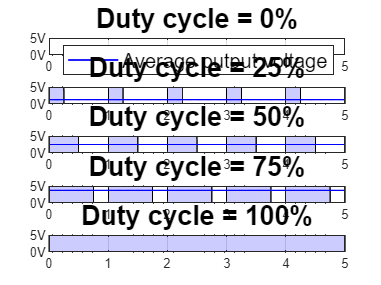

% The following parameters can me modified at will:
Duty = [0, 25, 50, 75, 100];    % different duty cycles [%]
num_of_periods = 5;             % #periods
Tmax = 5;                       % Max time [s]
amp = 5;                        % amplitude [V]

freq = 1/(Tmax/num_of_periods);
t = linspace(0, Tmax, 5000);

for i = 1:length(Duty)
    
    subplot(length(Duty), 1, i);

    f_duty = PWM(freq, 0, amp, Duty(i), t);
    f_avg = PWM(1/Tmax, 0, Duty(i)/100*amp, 100, t);
    fill([t fliplr(t)], [f_duty zeros(size(f_duty))], 'b', 'FaceAlpha', 0.2);
    hold on
    line_plot = plot(t, f_avg, 'b', 'LineWidth', 1);

    title("Duty cycle = " + string(Duty(i)) + "%", 'FontSize', 16);
    set(gca, 'ytick', [0 5]);
    set(gca, 'xtick', [0 1 2 3 4 5]);
    set(gca, 'yticklabel', {'0V', '5V'});
    ylim([0, 5]);
    grid on
    
    if i == 1
        legend(line_plot, {'Average output voltage'},'Location', 'northeast', 'FontSize', 12)
    end

end